# Generate Deliverables Doc

% Plug in fmincon optimized values
D = 2;
W = 4;
L = 1;
rho_full = 1250;
f_contour_quadratic = @(x, y)(D * (2*x/W).^2 <= y);
dividers = [D/3, 2*D/3];
densities = rho_full * [1, 0.5, 0.1];

f_rho = generate_density_func(dividers, densities);

## Simulate Boat:

f_simulate = @(phi)(boat_sim(phi, W, D, L, f_contour_quadratic, f_rho, true));

### Flat boat:

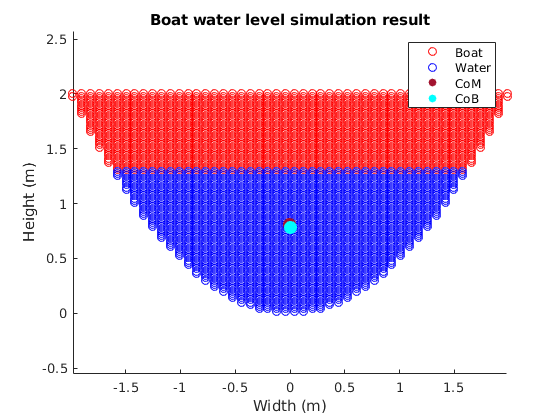

phi = 0;
f_simulate(phi);

### Heeled boat:

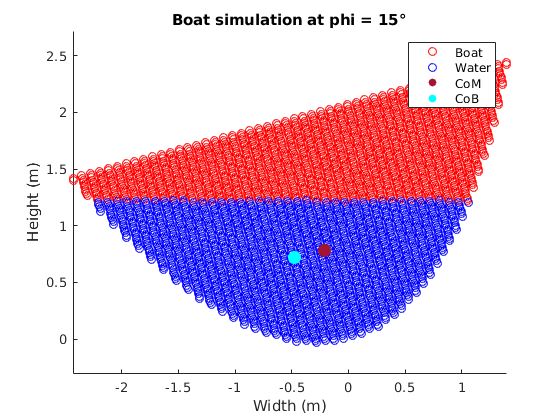

phi = 15;
f_simulate(phi);
title(sprintf("Boat simulation at phi = %d\\circ", phi))

### Heeled boat at AVS:

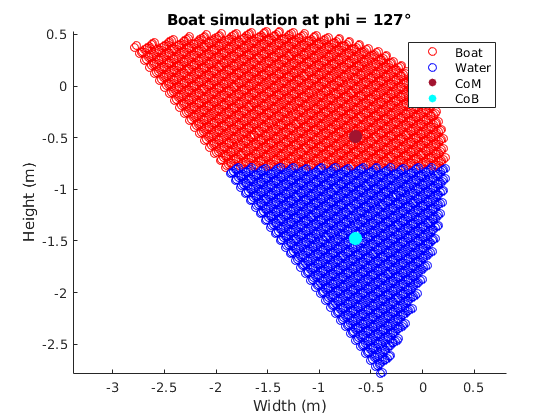

phi = calc_avs(W, D, L, f_contour_quadratic, f_rho);
f_simulate(phi);
title(sprintf("Boat simulation at phi = %d\\circ", phi))

## AVS Curve

[avs, v_phis, v_moment_arms] = calc_avs(W, D, L, f_contour_quadratic, f_rho);

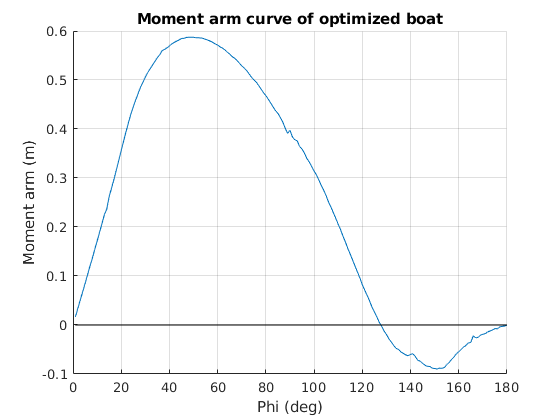

figure();
hold on;

plot(v_phis, v_moment_arms);
line([min(v_phis), max(v_phis)], [0, 0], 'color',' black');

grid on;
title("Moment arm curve of optimized boat")
xlabel("Phi (deg)");
ylabel("Moment arm (m)")

function f_rho = generate_density_func(dividers, densities)
    densities = abs(densities);
    f_rho = @(y)( (y <= dividers(1))*densities(1) + ...
            (y > dividers(1) & y <= dividers(2))*densities(2) + ...
            (y > dividers(2))*densities(3) );
end